# Multi-Class Fault Classification Using Simulated Data

This section demonstrates how to use the **Diagnostic Feature Designer** app to extract and analyze features from the fault data generated in the previous section. These features can then be used in the **Classification Learner** app to train a machine learning model.

Using this [example](https://www.mathworks.com/help/predmaint/ug/multi-class-fault-detection-using-simulated-data.html), we create 240 MAT files that represent pump operation in 8 different modes. The only change made was setting the variable 'nPerGroup' to 30 instead of 125. The generated MAT files are placed in the folder 'DataSmall'.

Below, we do some preprocessing on the data to remove transients, resample, and create fault identification flags associated with each dataset. We will use these flags to extract features from our data and train a machine learning model for classification. We have the option below to load this preprocessed data from a previous session.

## Preprocess Pump Data

Below, choose whether we preprocess the raw data or load in the previously saved data that was already preprocessed.

- **Load Data: **Loads saved preprocessed data that was generated in a previous session (faster).

- **Preprocess Data*****: ***Preprocesses to remove transients, resample, set up fault identification flags, and gather data into memory.

data_option = "Load Data";

### Manage Data Using `simulationEnsemble`

The data in the MAT files has some transients associated with it in the initial 0.8 sec. We are only interested in the steady state behavior of the signal. The code below removes those transients and saves the steady state data in a new variable. 

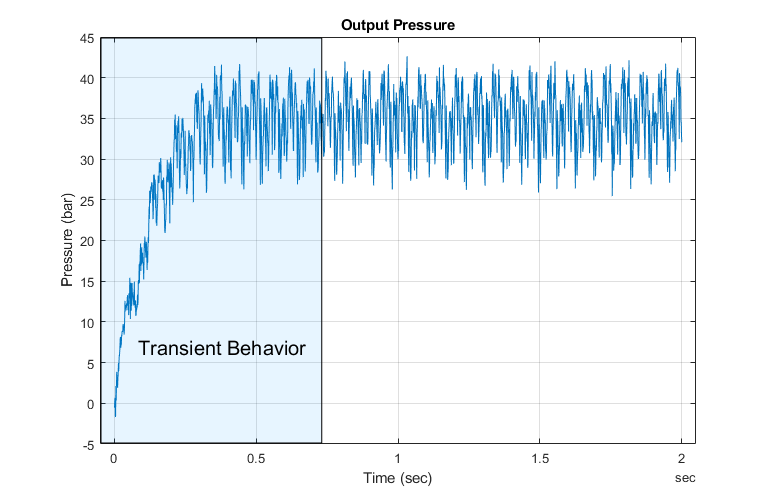

It also re-samples the data to ensure that it is uniformly sampled, and creates a fault identification flag based on the absence/presence of a particular fault. As there are 3 possible fault types (seal leak, blocked inlet, and bearing wear), we define a binary fault flag with 8 possible values.

if data_option == "Load Data"
    load pumpDataComplete.mat
    load featuresForClassification.mat

elseif data_option == "Preprocess Data"
    prj = currentProject;
    datapath = strcat(prj.RootFolder,'\Fault_Classification\DataSmall');
    ens = simulationEnsembleDatastore(datapath);

    % Create new variables that will store the resampled data for the pressure
    % and flow signals, and the fault flag value
    ens.DataVariables = [ens.DataVariables;"flow";"pressure";"faultCode"];

    % Read data in a loop and write back the new variables to the same file
    while (hasdata(ens))
        data = read(ens);
        [dataToWrite] = preprocess(data);
        writeToLastMemberRead(ens,dataToWrite);
    end

ens =   simulationEnsembleDatastore with properties:

           DataVariables: [14×1 string]
    IndependentVariables: [0×0 string]
      ConditionVariables: [0×0 string]
       SelectedVariables: [3×1 string]
                ReadSize: 1
              NumMembers: 240
          LastMemberRead: "C:\Users\tzhu\Downloads\PumpMaintenance-master\PumpMaintenance-master\Fault_Classification\DataSmall\pdmRecipPump_log_99.mat"
                   Files: [240×1 string]


Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 4 workers.

tt =

  M×3 tall table

           flow                pressure         faultCode
    __________________    __________________    _________

    {1201×1 timetable}    {1201×1 timetable}         0   
    {1201×1 timetable}    {1201×1 timetable}         0   
    {1201×1 timetable}    {1201×1 timetable}       100   
    {1201×1 timetable}    {1201×1 timetable}       100   
    {1201×1 timetable}    {1201×1 timetable}       100   
    {1201×1 timetable}    {1201×1 timetable}       100   
    {1201×1 timetable}    {1201×1 timetable}       100   
    {1201×1 timetable}    {1201×1 timetable}       100   
            :                     :                 :

Evaluating tall expression using the Parallel Pool 'Processes':
- Pass 1 of 1: Completed in 8.6 sec
Evaluation completed in 8.7 sec


### Using Tall Arrays & Gathering Data In-Memory

In this case, as the dataset is small enough, we will load the pressure, flow, and fault code values into a single, in-memory table. If the dataset is too large, we can continue using the ensemble object directly with the App which would then read/write data directly from the MAT files.

    ens.SelectedVariables = ["flow","pressure","faultCode"]
    tt = tall(ens)
    pumpDataInMemory = gather(tt);
end

## Partition Data for Training and Testing

We will set aside 20% of our data for testing or predictive model. This helps prevent overfitting by testing our trained model on data that the model has never seen before.

c = cvpartition(pumpDataInMemory.faultCode,'HoldOut',0.2);

trainData = pumpDataInMemory(training(c),1:2);
trainDataLabels = pumpDataInMemory(training(c),3);
trainDataAndLabels = [trainData trainDataLabels];

testData = pumpDataInMemory(test(c),1:2);
testDataLabels = pumpDataInMemory(test(c),3);
testDataAndLabels = [testData testDataLabels];

## Extract Features with Diagnostic Feature Designer App

Now that we have our data loaded in memory, it is often challenging to determine which features to select and how important these features are. The [Diagnostic Feature Designer App](http://web%28fullfile%28docroot%2C%20%27predmaint/ref/diagnosticfeaturedesigner-app.html'))) from the Predictive Maintenance Toolbox simplifies this workflow by interactively allowing you to explore your data visually by plotting and interacting with your ensemble memebers together, convert your data into different forms (time-domain vs frequency-domain), generate features of various types, and rank these features to establish which ones are the most effective. You can then generate a script that can re-process these features.

The following command will bring up the app, or you can find it in the Apps tab. Use the `TrainDataAndLabels` variable when importing data from the workspace.

diagnosticFeatureDesigner

Click on "New Session"

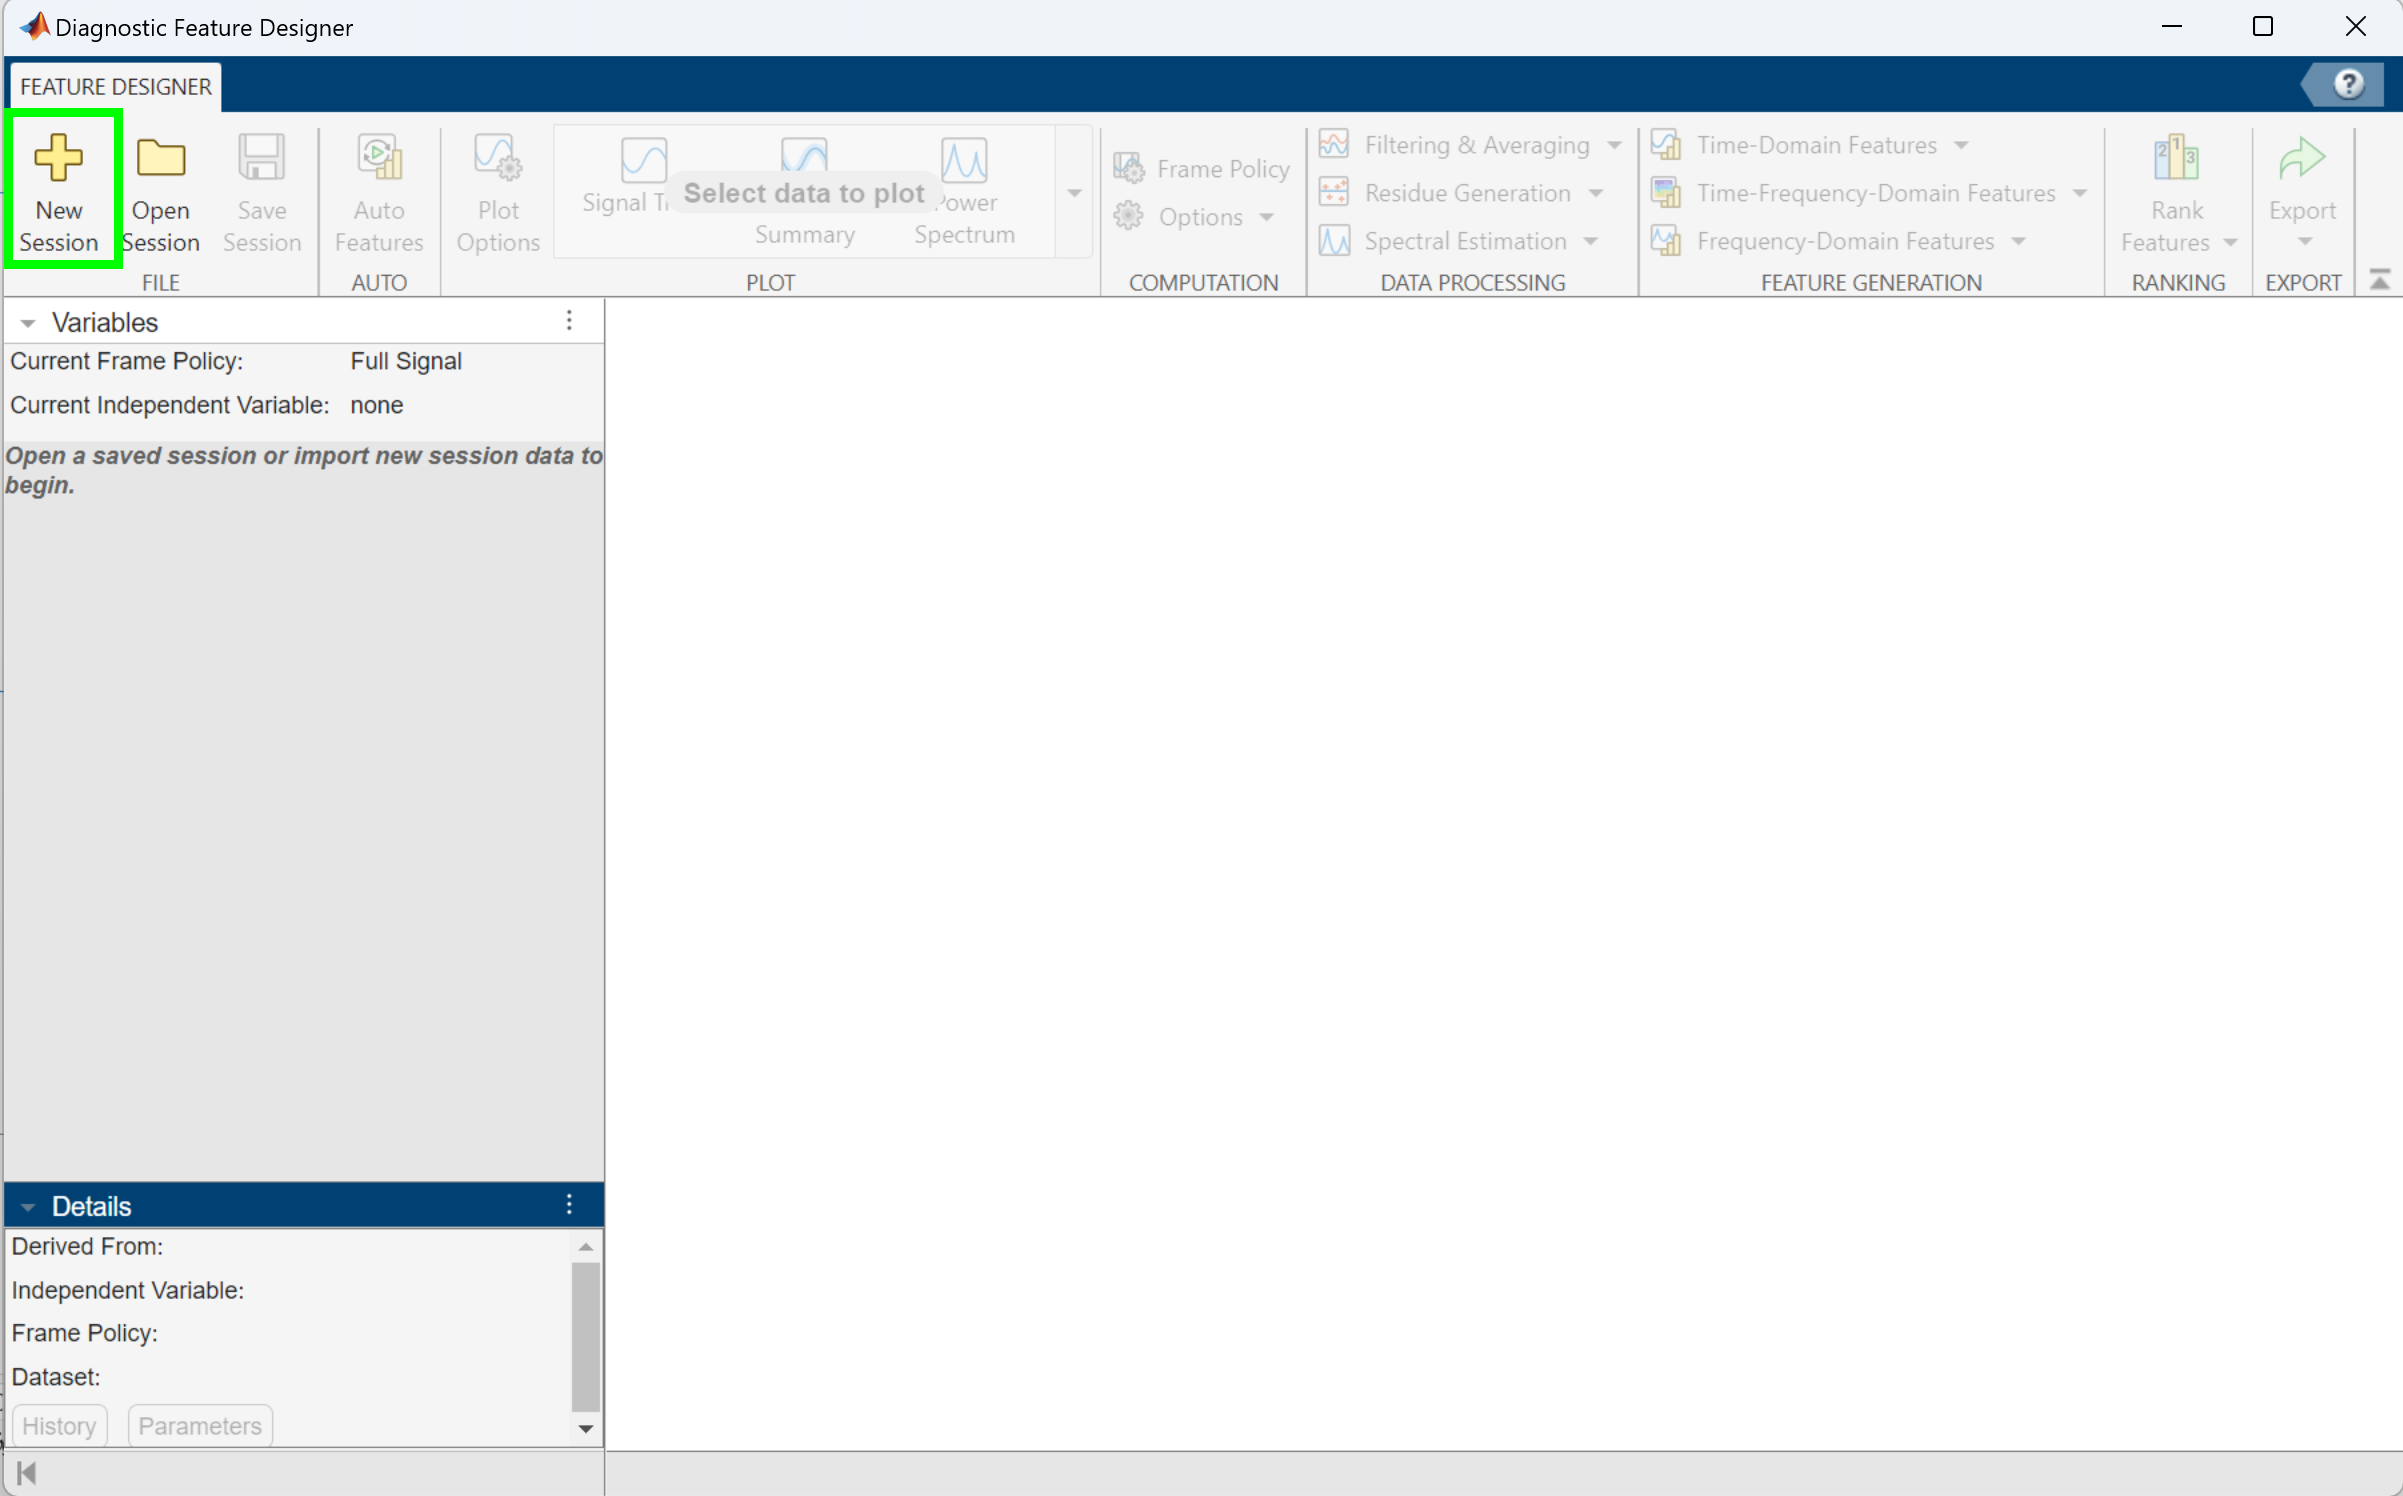

In **Select dataset to import **panel, select `trainDataAndLabels` as "Source".

In **Select source variables** panel, check `faultCode`.

In **Configure source variable properties**, select "Condition Variable" for **Variable type**.

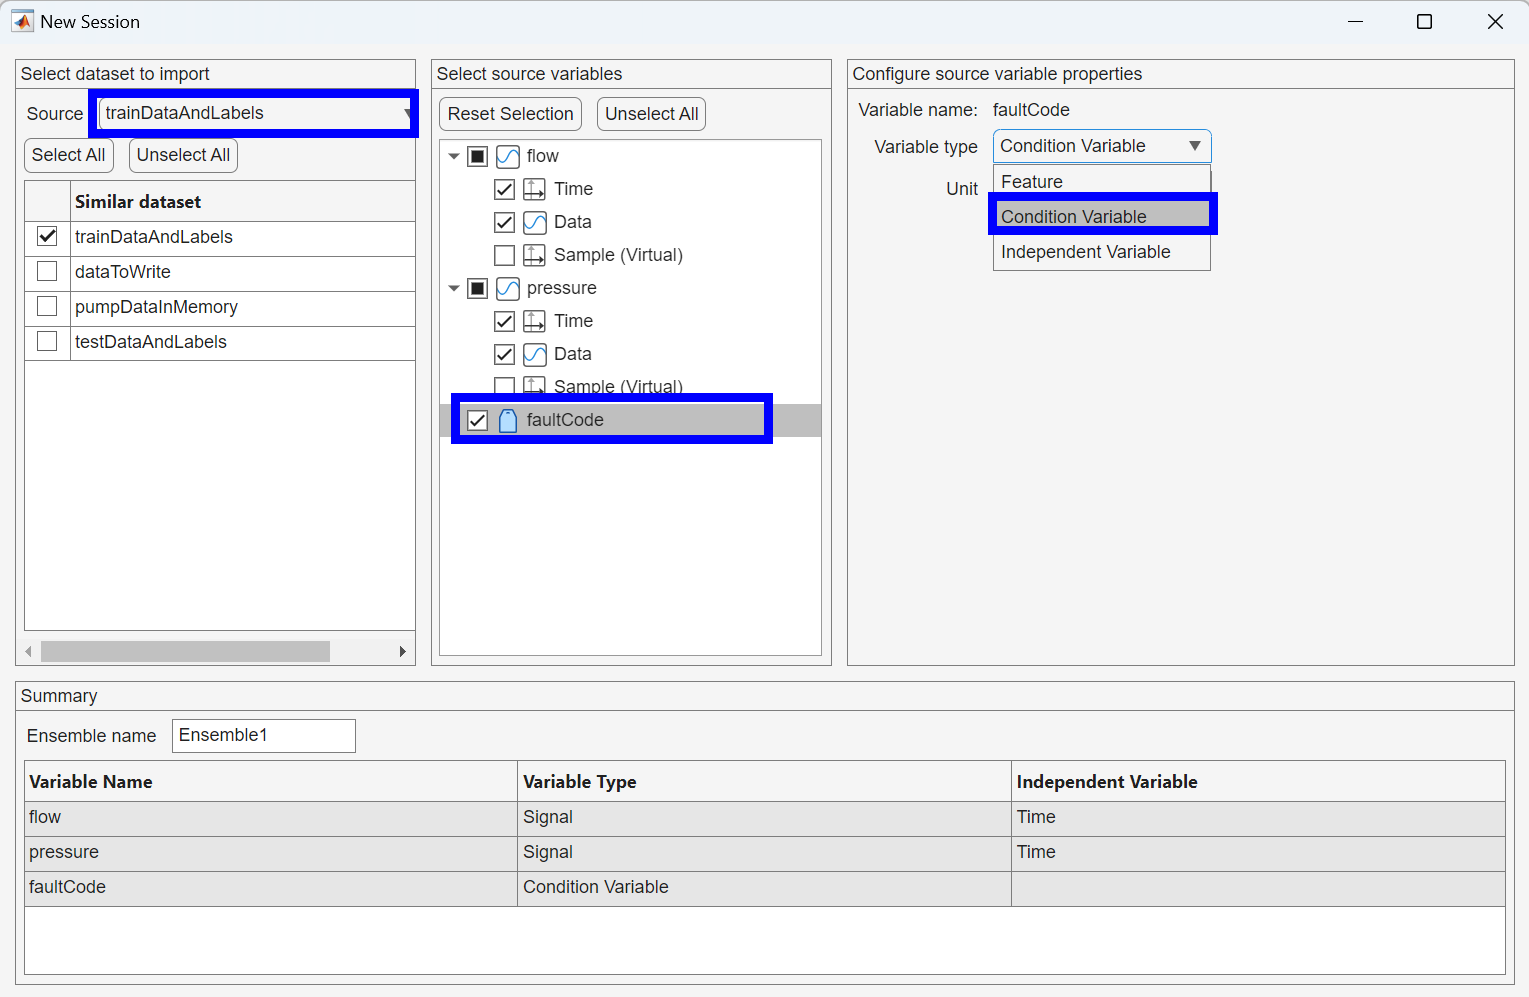

Click "Import" to continue.

Highlight "Full Signal" under "Signals" and click on "Auto Features" in the toolstrip. In the new dialog, check "Plot feature histograms" and click "Compute" to start automatic feature extraction process.

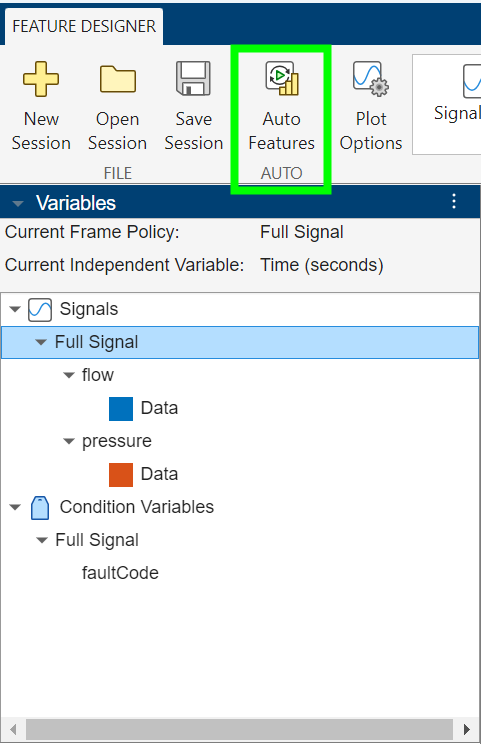      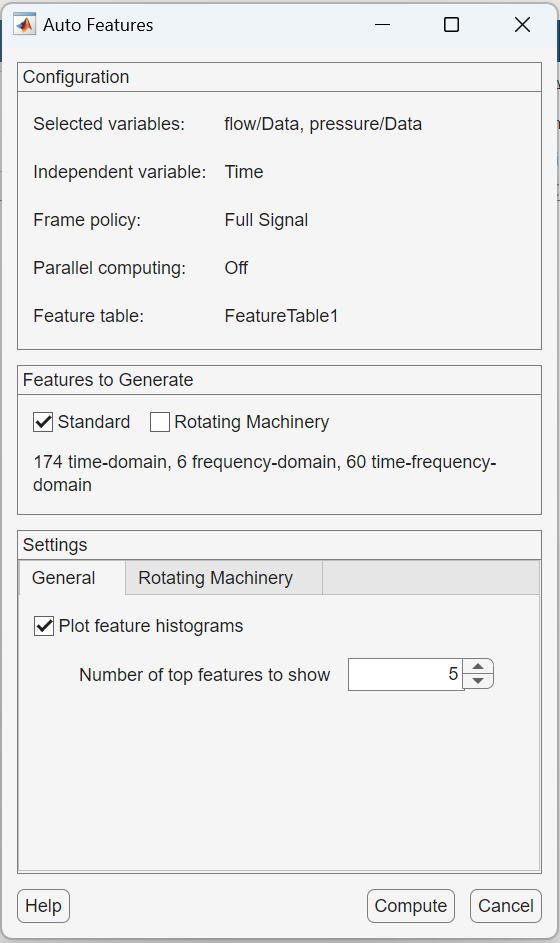

Once the process is complete, you will see a ranked list of features extracted from the original data set:

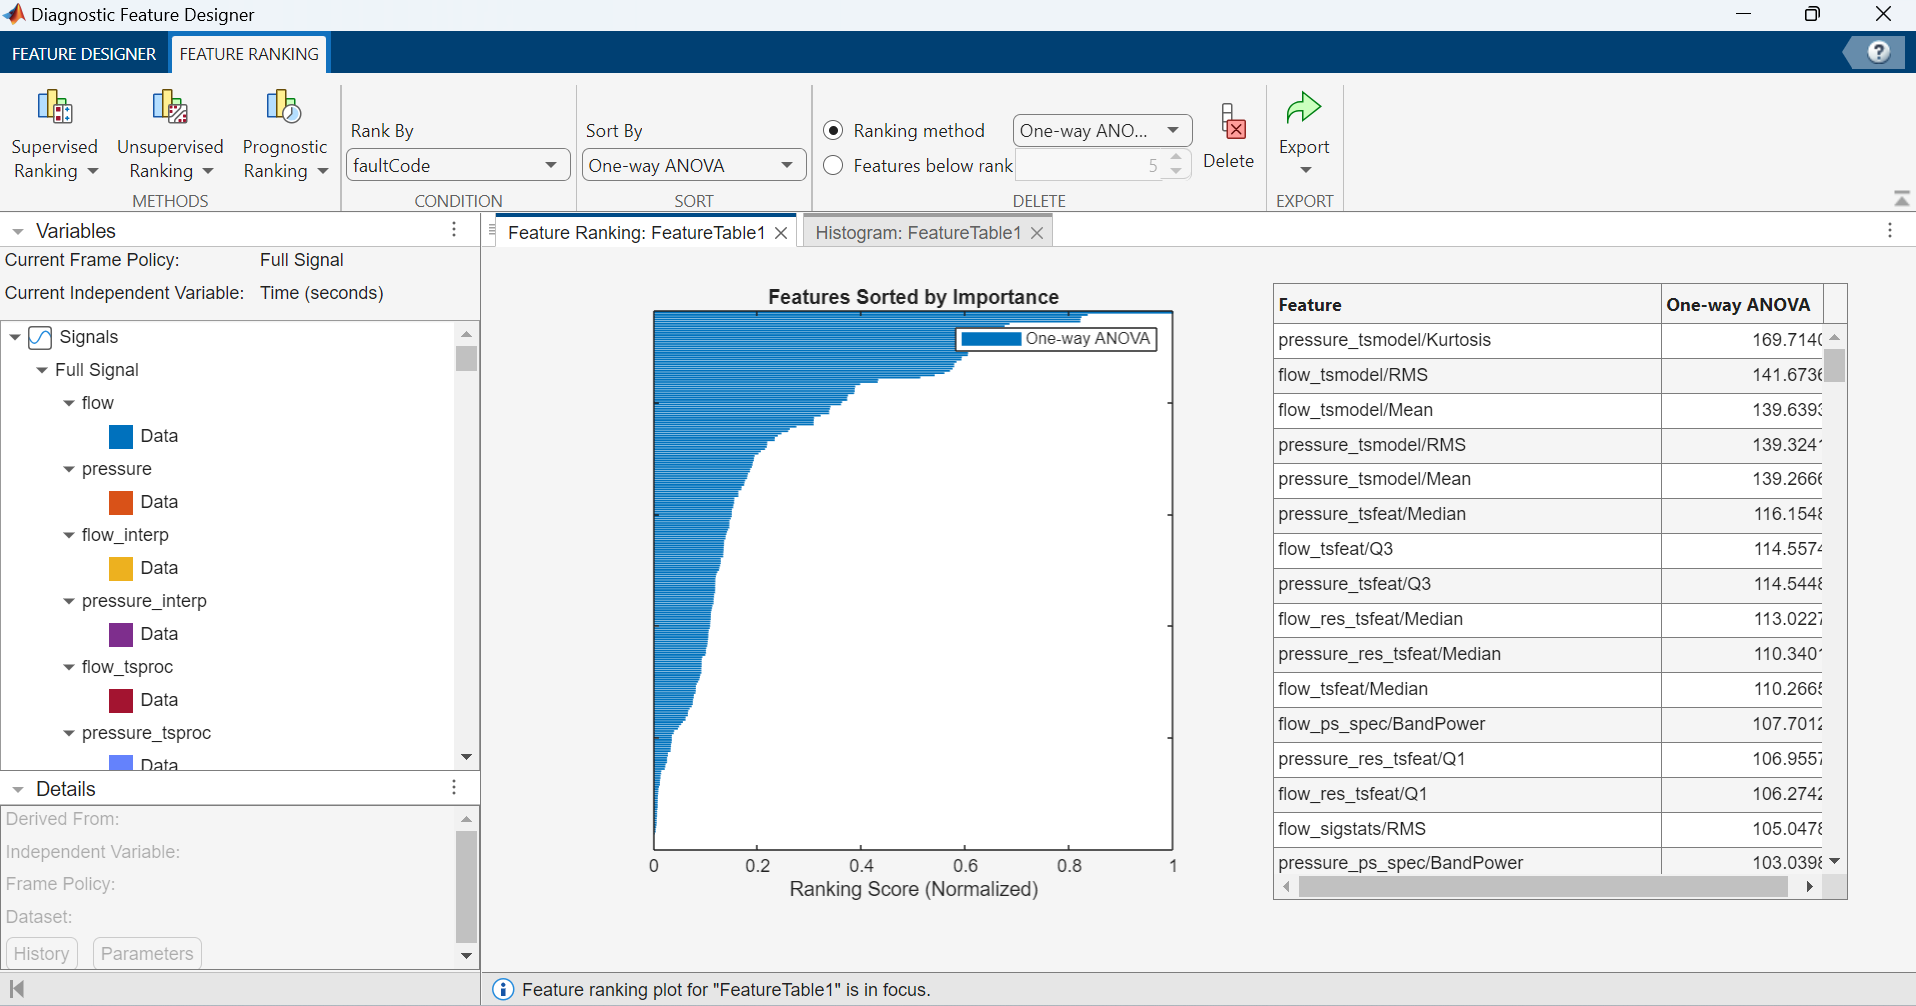

We can select the top 5 features and delete the rest of them.

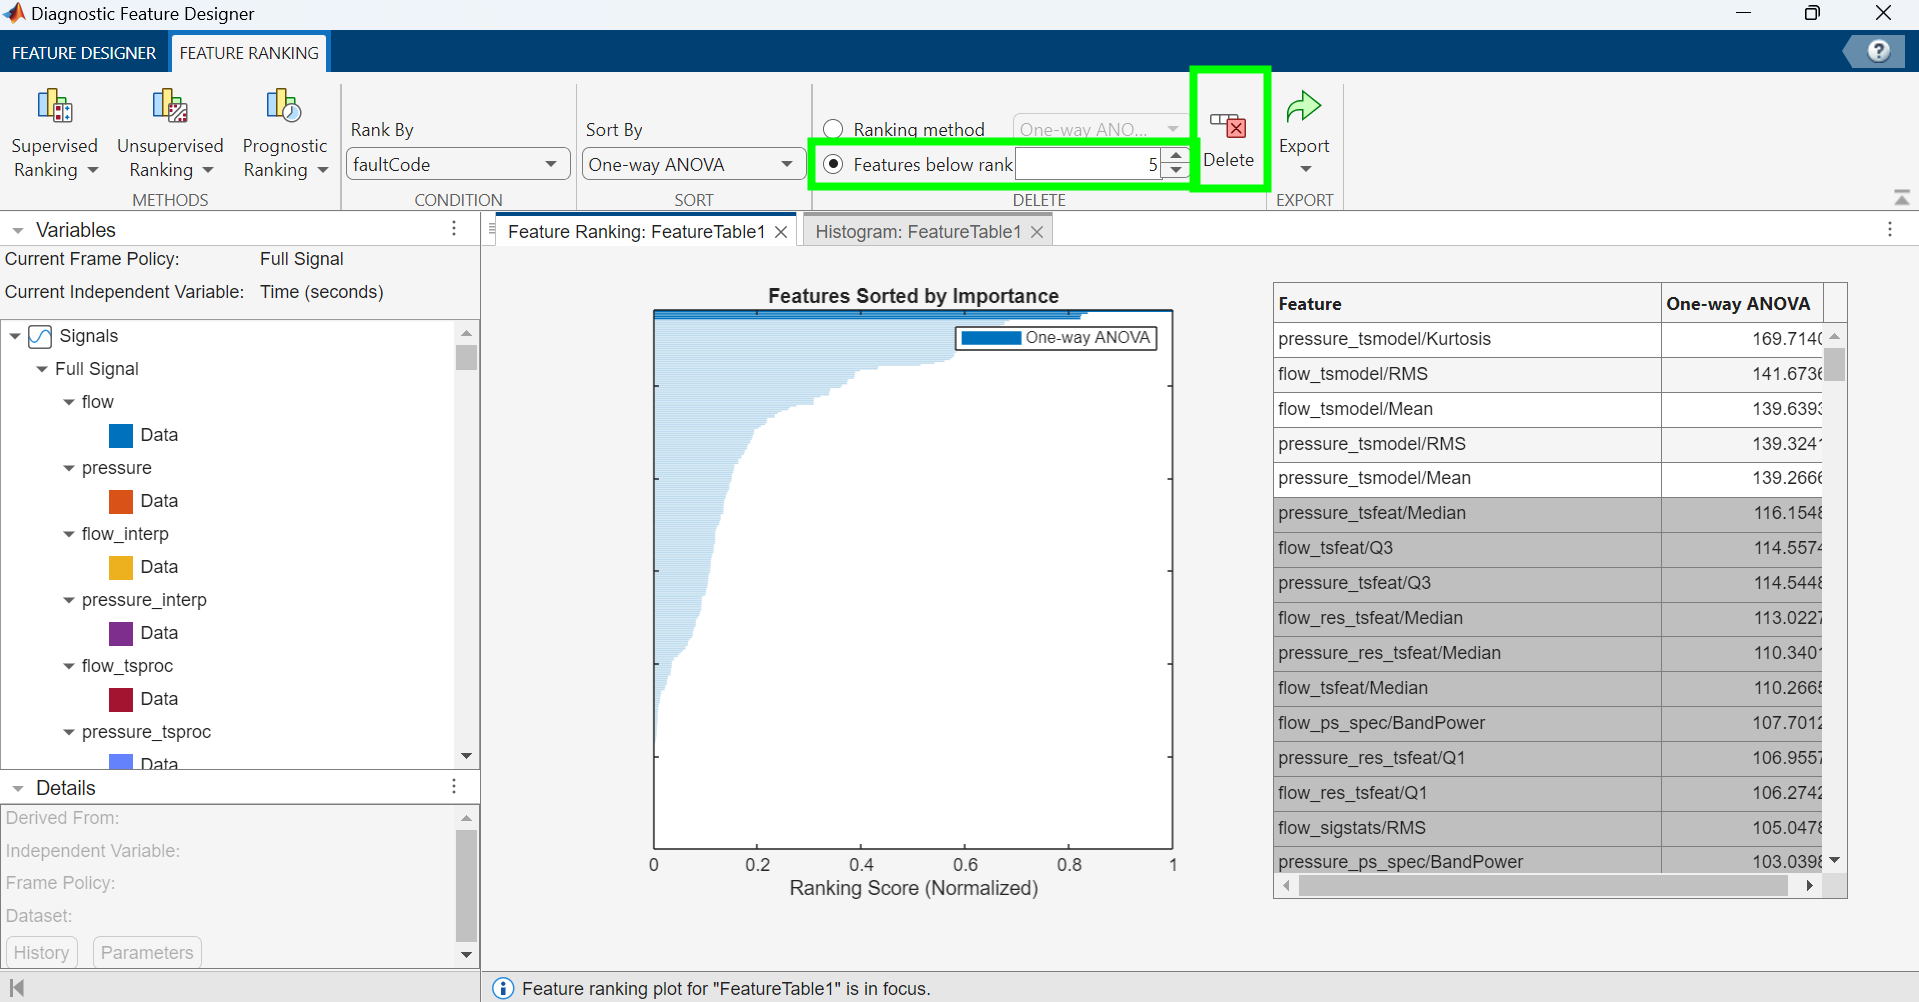

We will see the remaining 5 top features in the histogram:

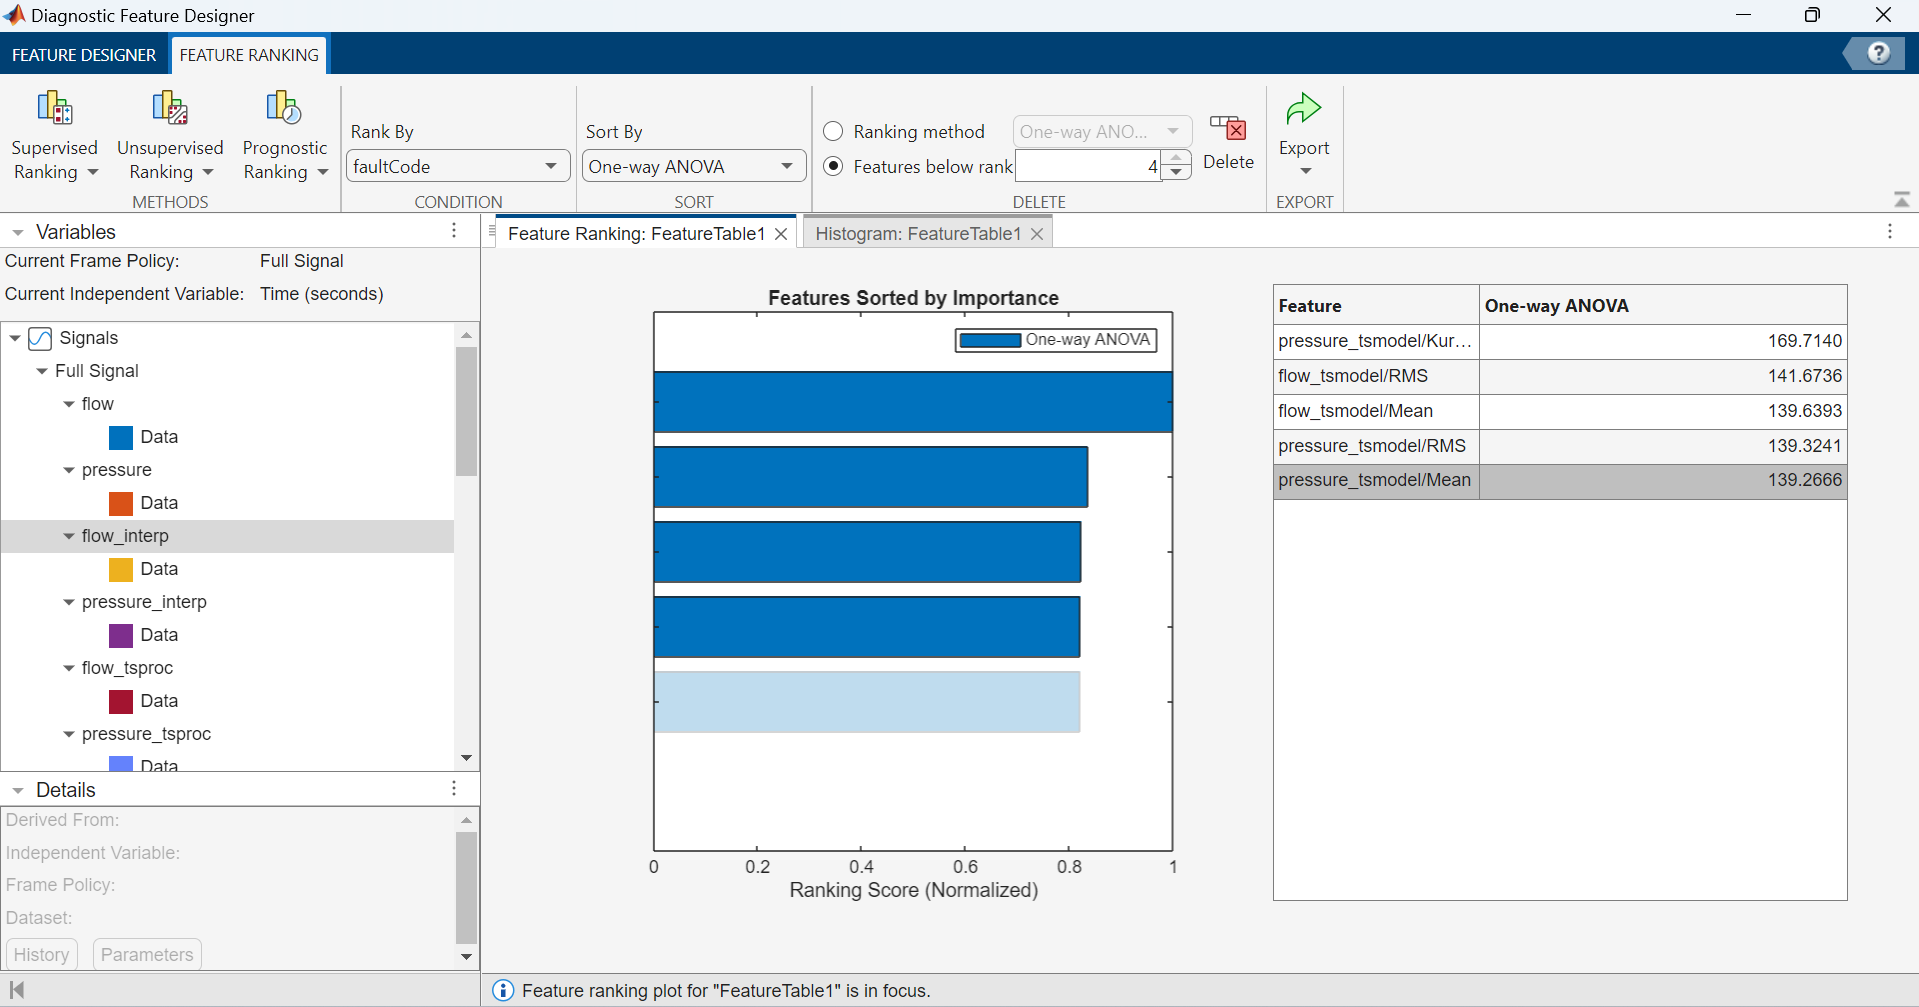

If you click **Export** in the toolstrip, you will see different options for exporting the engineered features:

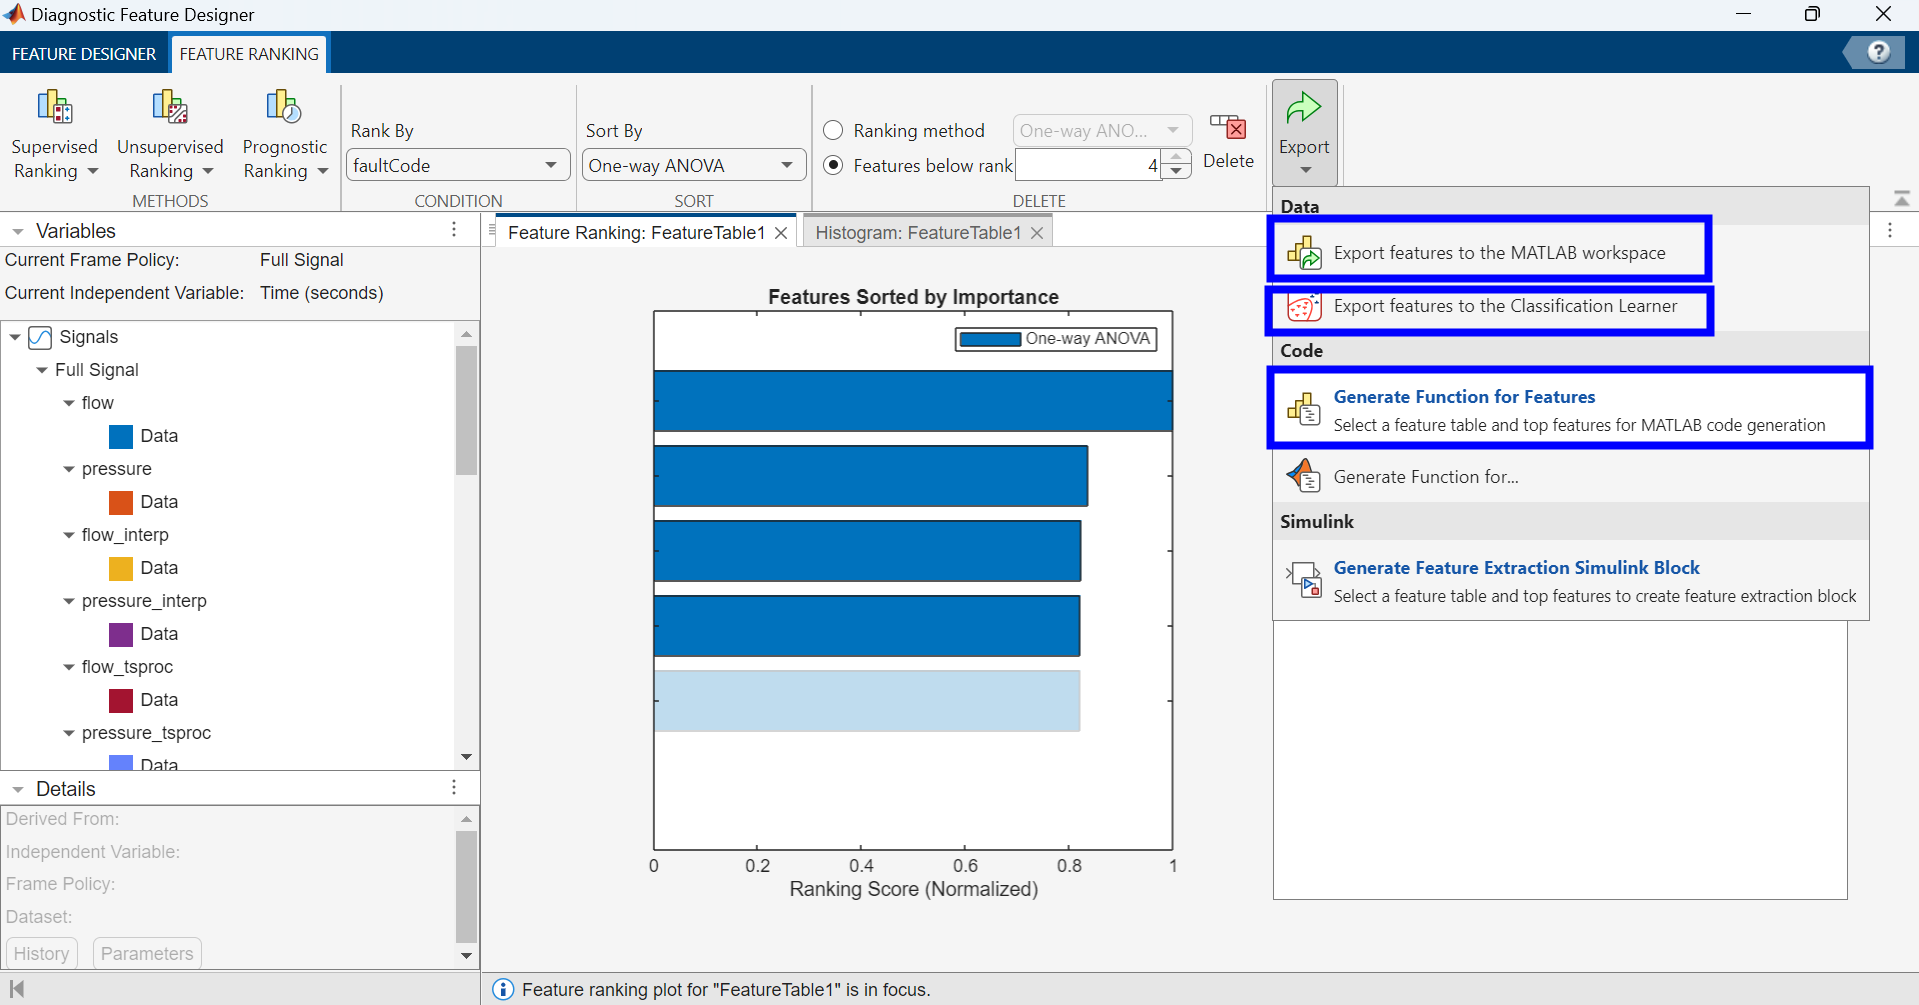

In this case, we will generate a function so that this process is repeatable later on. Select **Generate Function for Features**. In the new dialog, set Number of Features to 5. Save the new code file (with the default name `diagnosticFeatures`) to the current file directory.

We can generate the engineered features along with the response using the function:

[FeatureTable1, ~] = diagnosticFeatures(trainDataAndLabels);

## Train & Test a Classifier with Classification Learner App

One of the biggest challenges in machine learning is that there is no good way to know ahead of time what machine learning algorithm will work best until you try them and see. The [Classification Learner App](matlab: web(fullfile(docroot, 'stats/classification-learner-app.html'))) from the Statistics and Machine Learning Toolbox greatly simplifies this workflow. We can explore many different techniques in the app and see which method works best.

Now that we have our feature table, the next step is to train a classification model using the Classification Learner app. We can either export our Feature Table directly from the Diagnostic Feature Designer into the Classification Learner app, or export the features to the workspace for use in the Classification Learner app. 

The following command will bring up the app, or you can find it in the Apps tab.

classificationLearner

Click on "New Session" in the toolstrip and select "From Workspace":

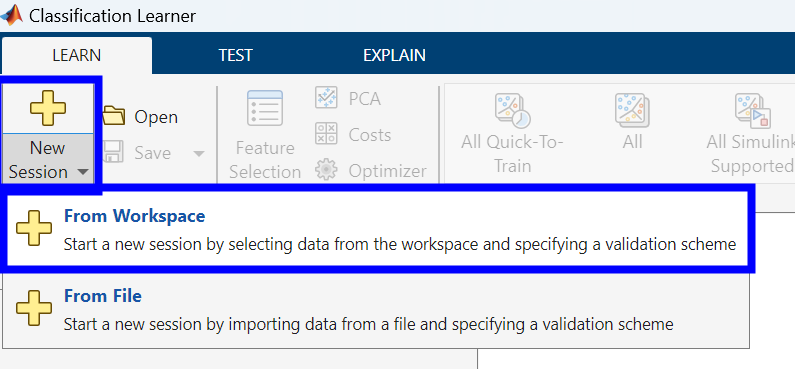

In **Data Set Variable** section, select `FeatureTable1`. In **Response** section, select `faultCode`. In **Predictors** section, select every item except for `faultCode`.

After these are set, click on "Start Session".

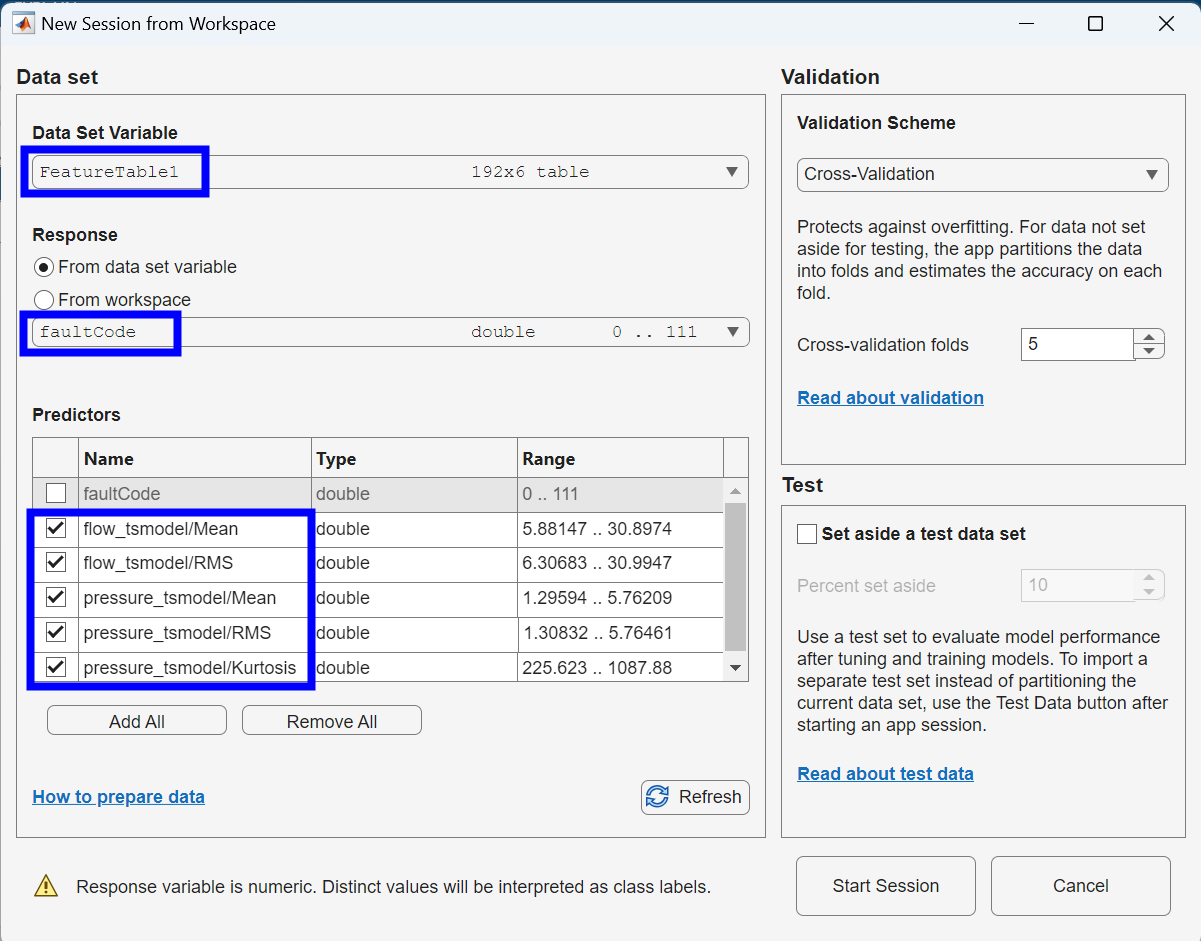

In the toolstrip, select **All**, click on **Use Parallel**, and click on **Train All**. This will initiate the autoML process where the app runs all classification algorithms on the dataset and determines which one has the best performance.

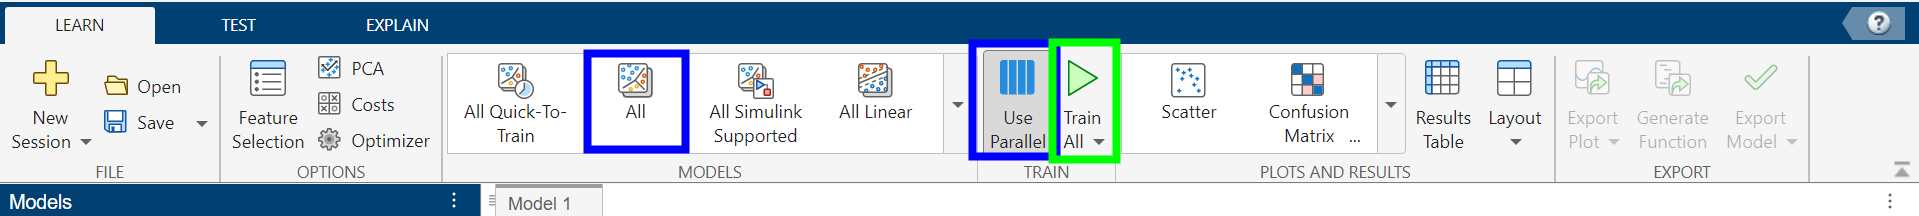

After all the models have run to completion, you can sort the results by validation accuracy as shown below. You can also turn on the Confusion Matrix plot to see the True Positive Rates (TPR) for multi-class classification.

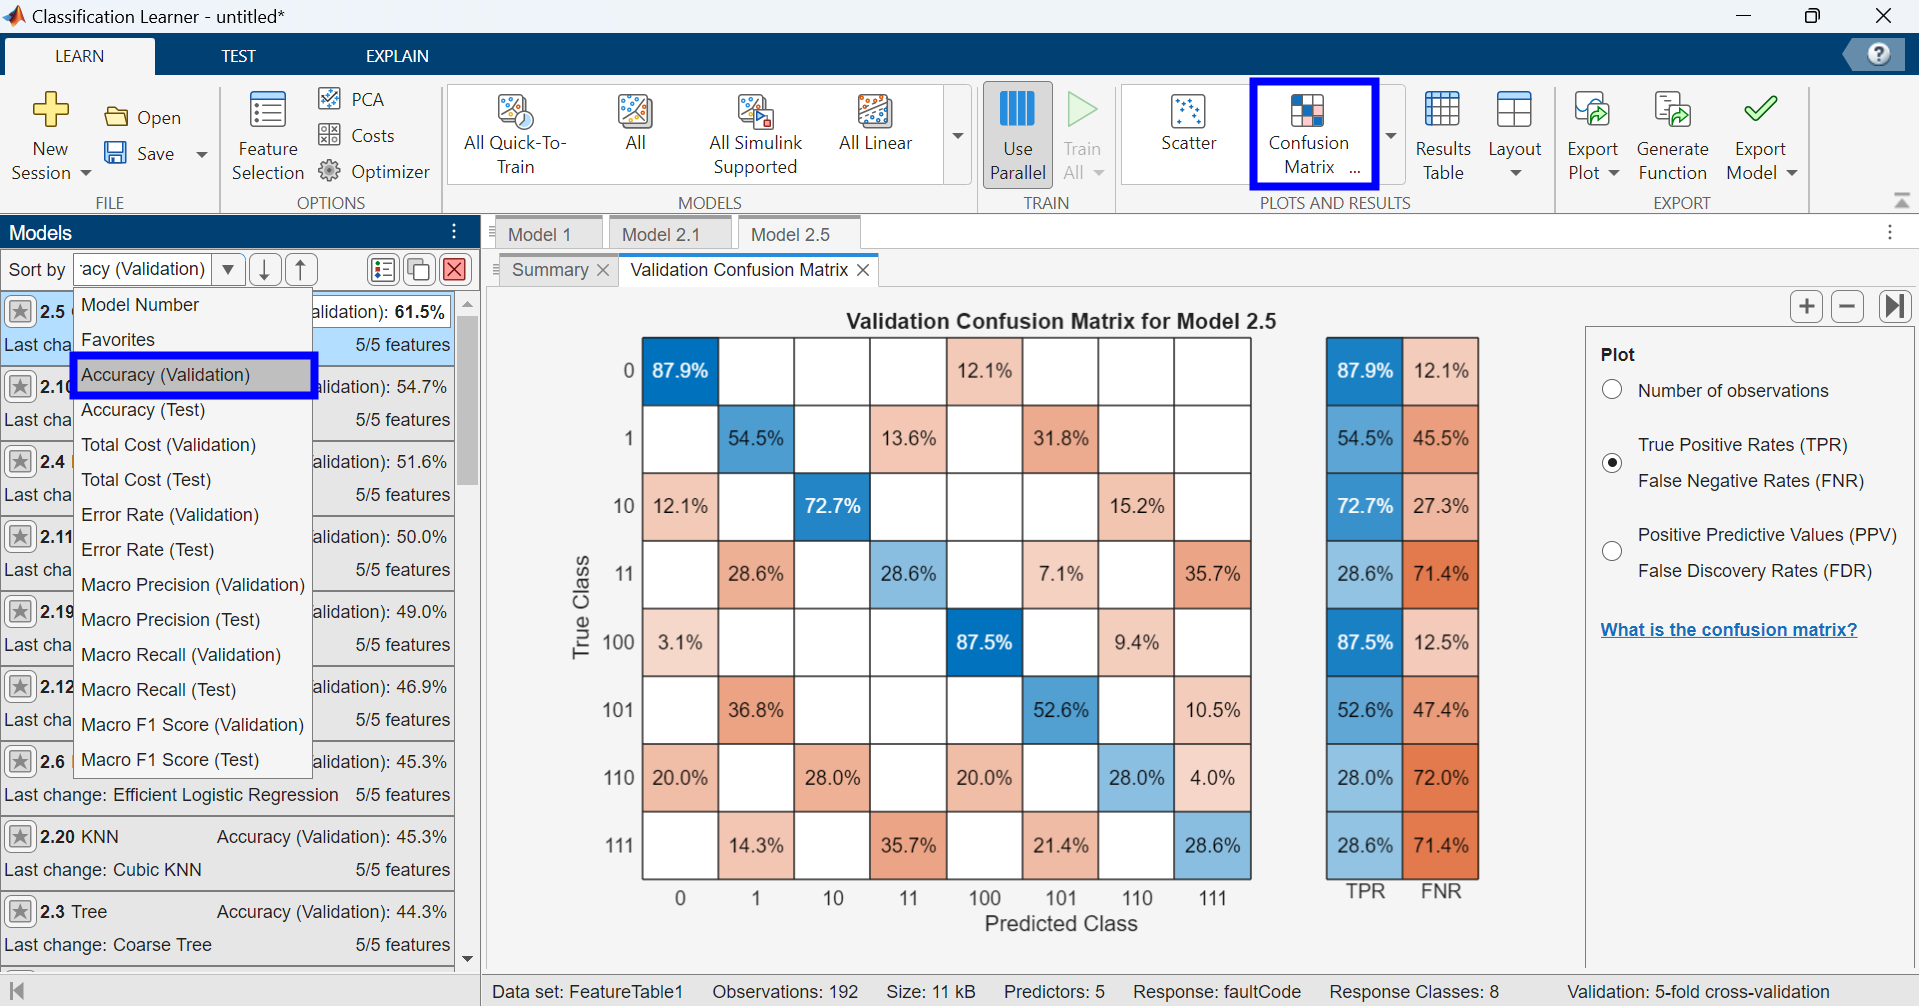

We can generate the model for making predictions using this classification algorithm by clicking on **Export Model**, and then **Export Model**.

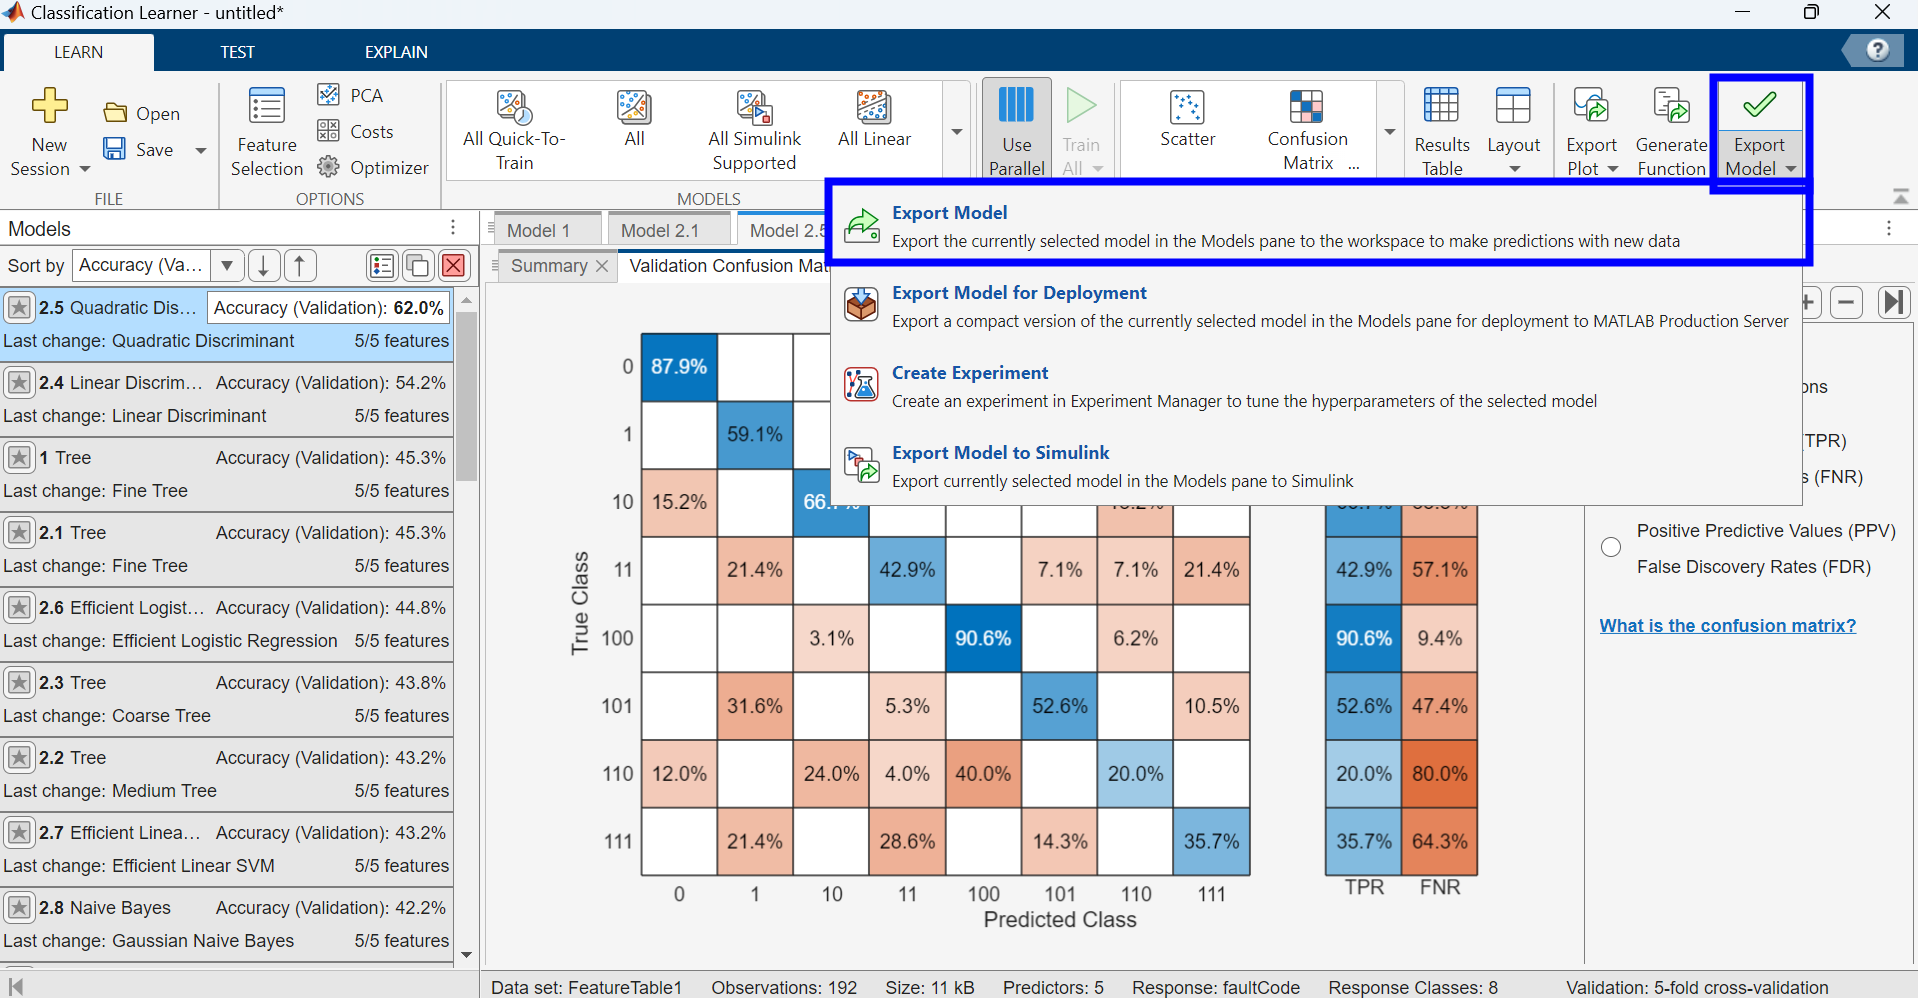

The model will be saved as a workspace variable with the default name `trainedModel`. You can also include the training data as part of the variable.

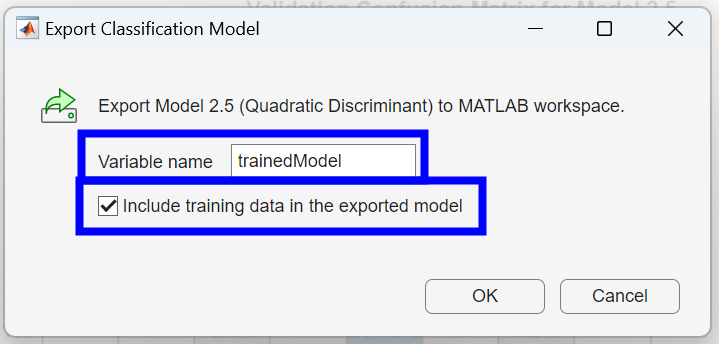

## Test Classifier Performance on New Data

To prevent overfitting, we need to test our classifier on our test data, which is data the model has never seen before. To do this, we will extract the same features from the test data, then use our trained classifier to predict the fault codes. We can then compare these predictions to the truth data to calculate the test accuracy of our model. 

% Generate features from test data
testFeatures = diagnosticFeatures1(testDataAndLabels);

% Use trained model to predict test data fault codes
predictedLabels = trainedModel1.predictFcn(testFeatures);

% Calculate test prediction accuracy
accuracy = sum(categorical(predictedLabels)==categorical(testDataLabels.Variables))/length(predictedLabels);
disp("Test Data Accuracy = "+100*accuracy+"%")

Test Data Accuracy = 68.75%


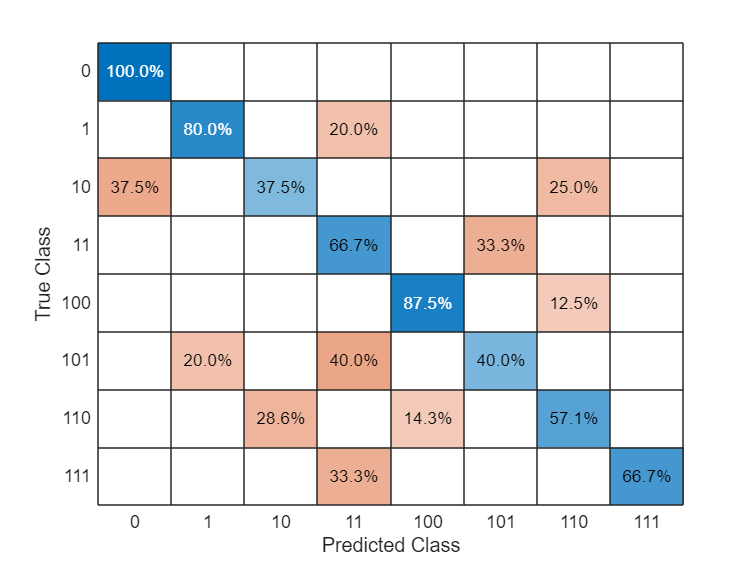

% View a confusion chart of the test data
confusionchart(categorical(testDataLabels.Variables), categorical(predictedLabels), "Normalization", "row-normalized");

We notice from the results of our test that the model performs well across certain categories, and poorly in others. There could be many reasons for this. For example, we may need to:

- Acquire more training data, especially in particular categories. In practice, fault data can be very difficult to acquire from hardware, because we don't want our machines to fail! To augment this, we could use Simulink to create a model of our system to generate synthetic fault data, which we can combine with the data from our hardware. 

- Extract different features from our original dataset. In this example, we used all of the generated features, but some irrelevant features may just be noise in our training. Good features are those that clearly indicate a separation between classes in our data. To help with the process of selecting the best features for training, we can [rank features](matlab: web(fullfile(docroot, 'predmaint/gs/rank-and-export-features-in-diagnostic-feature-designer.html#responsive_offcanvas'))) within the Diagnostic Feature Designer, or use the [feature selection algorithms](matlab: web(fullfile(docroot, 'stats/feature-selection.html'))).

- Use a different type of classifier, or use [hyperparameter optimization](matlab: web(fullfile(docroot, 'stats/hyperparameter-optimization-in-classification-learner-app.html'))) to optimize our classifier performance. This can be done within the Classification Learner App, or programmatically.

## Helper Functions

Preprocess data to remove transients and re-sample

function [dataToWrite] = preprocess(data)

    tMin = seconds(0.8);

    flow = data.qOut_meas{1};
    flow = flow(flow.Time >= tMin,:);
    flow.Time = flow.Time - flow.Time(1);
    pressure = data.pOut_meas{1};
    pressure = pressure(pressure.Time >= tMin,:);
    pressure.Time = pressure.Time - pressure.Time(1);

    % Ensure the flow and pressure is sampled at a uniform sample rate
    flow = retime(flow,'regular','linear','TimeStep',seconds(1e-3));
    pressure = retime(pressure,'regular','linear','TimeStep',seconds(1e-3));

    % Find the values of the fault variables from the SimulationInput
    simin = data.SimulationInput{1};
    vars = {simin.Variables.Name};
    idx = strcmp(vars,'leak_cyl_area_WKSP');
    LeakFault = simin.Variables(idx).Value;
    idx = strcmp(vars,'block_in_factor_WKSP');
    BlockingFault = simin.Variables(idx).Value;
    idx = strcmp(vars,'bearing_fault_frict_WKSP');
    BearingFault = simin.Variables(idx).Value;

    LeakFlag = LeakFault > 1e-6;
    BlockingFlag = BlockingFault < 0.8;
    BearingFlag = BearingFault > 0;
    CombinedFlag = LeakFlag+10*BlockingFlag+100*BearingFlag;

    dataToWrite.flow = flow;
    dataToWrite.pressure = pressure;
    dataToWrite.faultCode = CombinedFlag;

    dataToWrite = struct2table(dataToWrite,'AsArray',1);
end
